# Inverse Laplace Transform and Partial Fraction Expansion

## 1. Real and Distinct Poles

Given $F(s) = \frac{10}{s^2+8\,s+15}$

num = 10

num = 10

den = conv([1 3], [1 5])

den =      1     8    15


[r, p, k] = residue (num, den)

r =     -5
     5


p =     -5
    -3



k =

     []



We can interpret the output as


$$F(s) = \frac{-5}{s+5} + \frac{5}{s+3}$$


Taking the inverse Laplace transform yields


$$f(t) = 5\,{\mathrm{e}}^{-3\,t}-5\,{\mathrm{e}}^{-5\,t}$$


### Optional: Check with MATLAB's symbolic math toolbox

Define it as a function to avoid the copy and paste.

inverse_laplace_sym(num, den)

$$Fs = \frac{10}{s^{2}+8\,s+15}$$

$$Fs\_pf = \frac{5}{s+3}-\frac{5}{s+5}$$

$$f = 5\,{\mathrm{e}}^{-3\,t}-5\,{\mathrm{e}}^{-5\,t}$$


function [] = inverse_laplace_sym(num, den)
    syms s
    nums = poly2sym(num, s);
    dens = poly2sym(den, s);
    Fs = nums / dens
    Fs_pf = partfrac(Fs)
    f = ilaplace(Fs)
end

## 2. Real and Repeated Poles

Given


$$F(s) = \frac{10}{(s+3)(s+5)^2$$


find $f(t)$

num = 10
den = conv([1 3], conv([1 5],[1 5]))
[r, p, k] = residue (num, den)

Interpret the output as


$$
F(s) =-\frac{2.5}{\,\left(s+5\right)} - \frac{5}{{\left(s+5\right)}^2} +  \frac{2.5}{\,\left(s+3\right)} $$


Taking inverse Laplace


$$f(t) = -2.5\,{\mathrm{e}}^{-5\,t}- 5\,t\,{\mathrm{e}}^{-5\,t} + 2.5\,{\mathrm{e}}^{-3\,t}}$$


### Symbolic check

Use the function we defined above.

inverse_laplace_sym(num, den)

$$Fs = \frac{10}{s^{2}+8\,s+15}$$

$$Fs\_pf = \frac{5}{s+3}-\frac{5}{s+5}$$

$$f = 5\,{\mathrm{e}}^{-3\,t}-5\,{\mathrm{e}}^{-5\,t}$$

## 3. Imaginary Poles (Complex with zero real component)

Given


$$F(s) = \frac{3\,s+1}{s\,(s^2+9)}$$


find $f(t)$

num = [3 1]

num =      3     1


den = [1 0 9 0]

den =      1     0     9     0


[r, p, k] = residue(num, den)

r =   -0.0556 - 0.5000i
  -0.0556 + 0.5000i
   0.1111 + 0.0000i


p =    0.0000 + 3.0000i
   0.0000 - 3.0000i
   0.0000 + 0.0000i



k =

     []



Interpret the results with

 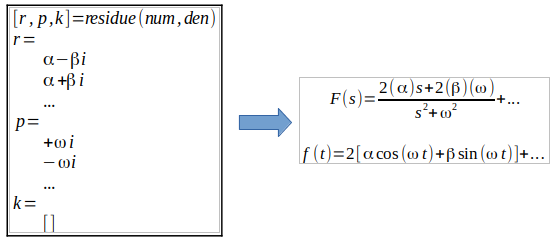


$$F(s) = \frac{2 \, (-0.056 \,s)}{s^2 + (3)^2} + \frac{2 \, (0.5)(3)}{s^s + (3)^2} + \frac{0.11}{s}$$



$$f(t) = 2 \left[ (-0.056) \cos{(3\,t)} + (0.5) \sin{(3\,t)} \right] + 0.11$$


## Symbolic check

inverse_laplace_sym(num, den)

$$Fs = \frac{3\,s+1}{s^{3}+9\,s}$$

$$Fs\_pf = \frac{1}{9\,s}-\frac{\frac{s}{9}-3}{s^{2}+9}$$

$$f = \sin\left(3\,t\right)-\frac{\cos\left(3\,t\right)}{9}+\frac{1}{9}$$

## 4. Complex Poles

Given


$$F(s) = \frac{25}{(s+10) \, \left(\,(s+5)^2 + 4^2\,\right)} = \frac{25}{s^3 + 20s^2+ 141 s + 410$$


find $f(t)$

num = 25;
den = conv([1, 10], conv([1 5],[1 5]) + [0 0 4^2])

den =      1    20   141   410


den = [1 20 141 410]

den =      1    20   141   410


[r, p, k] = residue(num, den)

r =    0.6098 + 0.0000i
  -0.3049 - 0.3811i
  -0.3049 + 0.3811i


p =  -10.0000 + 0.0000i
  -5.0000 + 4.0000i
  -5.0000 - 4.0000i



k =

     []



Interpret the residue output

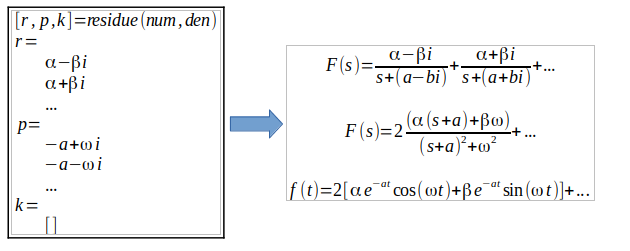


$$F(s) = \frac{0.610}{s+10} \ + 2 \left[ \frac{(-0.305) \, (s+5)}{ (s+5)^2+(4)^2 } + \frac{(0.381)(4)} { (s+5)^2+(4)^2 } \right]$$



$$f(t) = (0.610)\text{e}^{-10\,t} + 2 \left[ (-0.305) \, \text{e}^{-5 \, t} \cos{(4 \, t)} + (0.381)\text{e}^{-5 \, t} \sin{(4 \, t)} $$


### Symbolic Check

inverse_laplace_sym(num, den)

$$Fs = \frac{25}{s^{3}+20\,s^{2}+141\,s+410}$$

$$Fs\_pf = \frac{25}{41\,\left(s+10\right)}-\frac{25\,s}{41\,\left(s^{2}+10\,s+41\right)}$$

$$f = \frac{25\,{\mathrm{e}}^{-10\,t}}{41}-\frac{25\,{\mathrm{e}}^{-5\,t}\,\left(\cos\left(4\,t\right)-\frac{5\,\sin\left(4\,t\right)}{4}\right)}{41}$$